# Script01_状態平均化モデルの算出

Copyright (c) 2022, The MathWorks, Inc.All rights reserved.

本スクリプトではシンプルなBuckコンバータを題材に

状態平均化モデルを導出する。

**代数演算ツールを使うことで手計算で求めた代数演算の検算が可能であることを確認する**

## 1．対象回路の定義

図１にBuckコンバータの回路図を示す。入力電圧は$V_{\textrm{in}}$とし、出力電圧は負荷抵抗(Ro)の両端電圧を$v_{\textrm{out}}$とする。

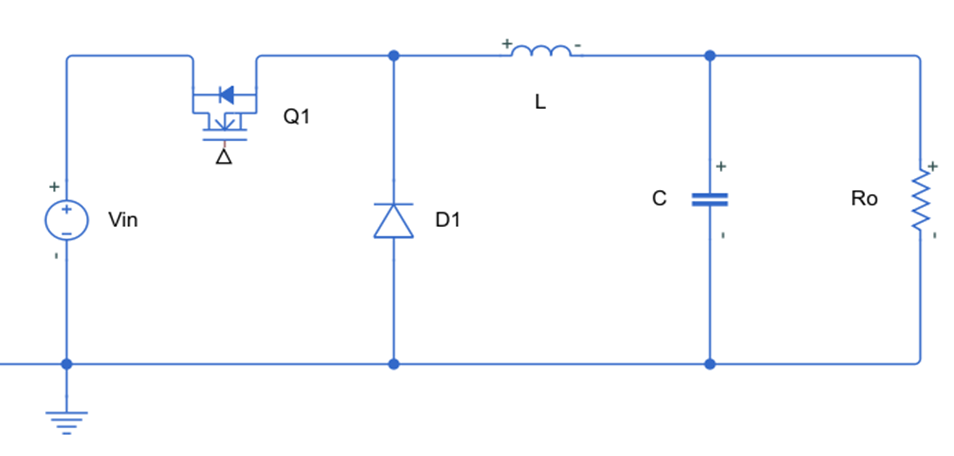

図１：Buckコンバータ回路図

## 2．スイッチがON状態での状態空間モデルを求める

まず、スイッチがON状態の微分方程式を立てる。

スイッチQ1がONの際に回路に流れる電流は下記図２のとおりになる。

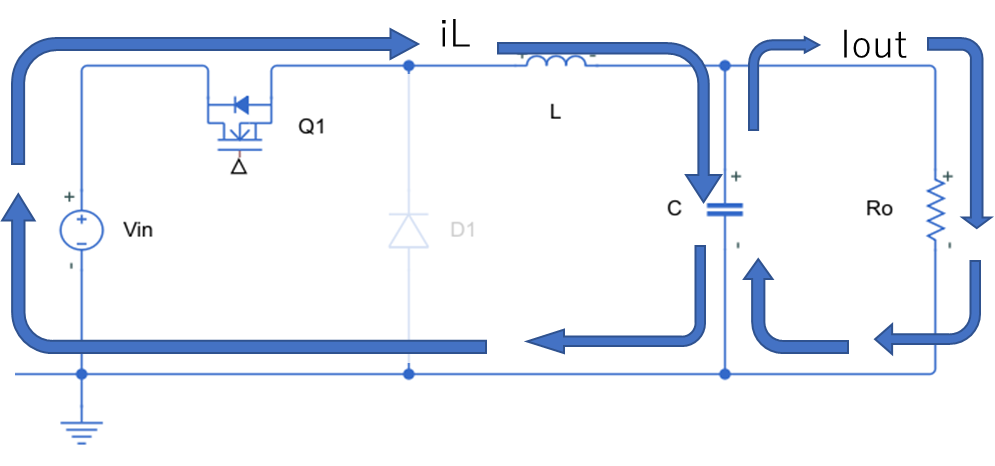

図２：スイッチON時におけるBuckコンバータ回路と電流経路

この回路を元に微分方程式を立てていく。

まず入力電圧$V_{\textrm{in}}$はインダクタ両端に発生する電圧$v_L$と出力電圧$v_{\textrm{out}}$との和であるため、


$$V_{\textrm{in}\;} =v_L +v_{\textrm{out}} \cdots \left(2\ldotp 1\right)$$


$v_L$はインダクタ電流$i_L$を微分してインダクタンス$L$をかけたものと等しい。そのため下記式に書き換えることができる。


$$V_{\textrm{in}} =L_1 \frac{{\textrm{di}}_L }{\textrm{dt}}+v_{\textrm{out}} \cdots \left(2\ldotp 2\right)$$


次にコンデンサに流入する電流$i_C$を求める。コンデンサの両端電圧と流れる電流の関係式から


$$i_C =C_1 \frac{{\textrm{dv}}_C }{\textrm{dt}}\cdots \left(2\ldotp 3\right)$$


図２から、コンデンサには流入する電流$i_L$と流出する電流$I_{\textrm{out}}$が存在する。

キルヒホッフの電流則に従うと、コンデンサに流入する電流$i_C$は流出電流と流入電流の差で求められる。よって


$$i_C =i_L -I_{\textrm{out}} \cdots \left(2\ldotp 4\right)$$


$I_{\textrm{out}}$は


$$I_{\textrm{out}} =\frac{v_{\textrm{out}} }{R_o }\cdots \left(2\ldotp 5\right)$$


また、 出力電圧はコンデンサ電圧と等しいため


$$v_{\textrm{out}\;} =v_C \cdots \left(2\ldotp 6\right)$$


上記の式(2.2),(2.3),(2.4),(2.5),(2.6)を元に次式を得る。


$$\frac{{\textrm{di}}_L }{\textrm{dt}}=\frac{1}{L_1 }V_{\textrm{in}} -\frac{1}{L_1 }v_C \cdots \left(2\ldotp 7\right)$$



$$\frac{{d\;v}_{C\;} }{\textrm{dt}}=\frac{1}{C_1 }i_L -\frac{1}{{C_1 R}_O }v_C \cdots \left(2\ldotp 8\right)$$


インダクタ電流$i_L$とコンデンサ電圧$v_C$を状態変数として状態空間モデルとして整理し直す。

出力となる状態方程式はコンバータの出力電圧である$v_{\textrm{out}}$であるが式(2.6)よりすでに導出済みである。

微分方程式を元に各状態空間行列を得る。


$$\mathit{\mathbf{x}}\left(t\right)=\left\lbrack \begin{array}{c}
i_L \\
v_C 
\end{array}\right\rbrack$$

$$\cdots \left(2\ldotp 9\right)$$



$$\mathit{\mathbf{u}}\left(t\right)=V_{\textrm{in}}$$

$$\cdots \left(2\ldotp 10\right)$$



$$\begin{array}{l}
{\mathit{\mathbf{A}}}_{\textrm{on}} =\left\lbrack \begin{array}{cc}
0 & -\frac{1}{L_1 }\\
\frac{1}{C_1 } & -\frac{1}{{C_1 R}_O }
\end{array}\right\rbrack \cdots \left(2\ldotp 11\right)\\
{\mathit{\mathbf{B}}}_{\textrm{on}} =\left\lbrack \begin{array}{cc}
\frac{1}{L_1 } & 0\\
0 & 0
\end{array}\right\rbrack \cdots \left(2\ldotp 12\right)\\
\begin{array}{l}
{\mathit{\mathbf{C}}}_{\textrm{on}} =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \cdots \left(2\ldotp 13\right)\\
{\mathit{\mathbf{D}}}_{\textrm{on}} =\mathrm{０}\cdots \left(2\ldotp 14\right)
\end{array}
\end{array}$$


よって状態空間モデルは下記式となる


$$\begin{array}{l}
\overset{\cdot }{\mathit{\mathbf{x}}} \left(t\right)={\mathit{\mathbf{A}}}_{\textrm{on}} \mathit{\mathbf{x}}\left(t\right)+{\mathit{\mathbf{B}}}_{\textrm{on}} \mathit{\mathbf{u}}\left(t\right)\cdots \left(2\ldotp 15\right)\\
v_{\textrm{out}} \left(t\right)={\mathit{\mathbf{C}}}_{\textrm{on}} \mathit{\mathbf{x}}\left(t\right)+{\mathit{\mathbf{D}}}_{\textrm{on}} \mathit{\mathbf{u}}\left(t\right)\cdots \left(2\ldotp 16\right)
\end{array}$$


式(2.15),(2.16)に状態空間行列を代入すると


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
i_L \\
v_C 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -\frac{1}{L_1 }\\
\frac{1}{C_1 } & -\frac{1}{{C_1 R}_O }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_L \\
v_C 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\frac{1}{L_1 } & 0\\
0 & 0
\end{array}\right\rbrack \textrm{Vin}\cdots \left(2\ldotp 17\right)$$



$$v_{\textrm{out}} \left(t\right)=v_c \left(t\right)\cdots \left(2\ldotp 18\right)$$


となる。

MATLABではSynbolic MathToolboxを用いると代数式を記述することが可能になる。

状態空間行列を記述すると下記のようになる。

今回はBuck Converterという比較的シンプルな回路に適応したため、検算するほどでもないかもしれないが、

より複雑な回路を同様のスキームで解析する際に、

理論式の妥当性を確認するために計算機の計算結果を参考にすることは有効であると考える。

clear variables
%代数シンボルを定義
syms L1 C1 Ro;

%状態空間行列を定義
Aon = [0 -1/L1;1/C1 -1/C1/Ro]

$$Aon = \left(\begin{array}{cc} 0 & -\frac{1}{L_{1}}\\ \frac{1}{C_{1}} & -\frac{1}{C_{1}\,\mathrm{Ro}} \end{array}\right)$$

%Bon　Conかいてみましょう


## 3．スイッチがON状態での状態空間モデルを求める

次に、スイッチがOFF状態の微分方程式を立てる。

スイッチQ1がOFFの際に回路に流れる電流は下記図３のとおりになる。

入力電圧がスイッチQ1によって切断され、代わりにダイオードD1が導通するためインダクタ電流経路が変化する。

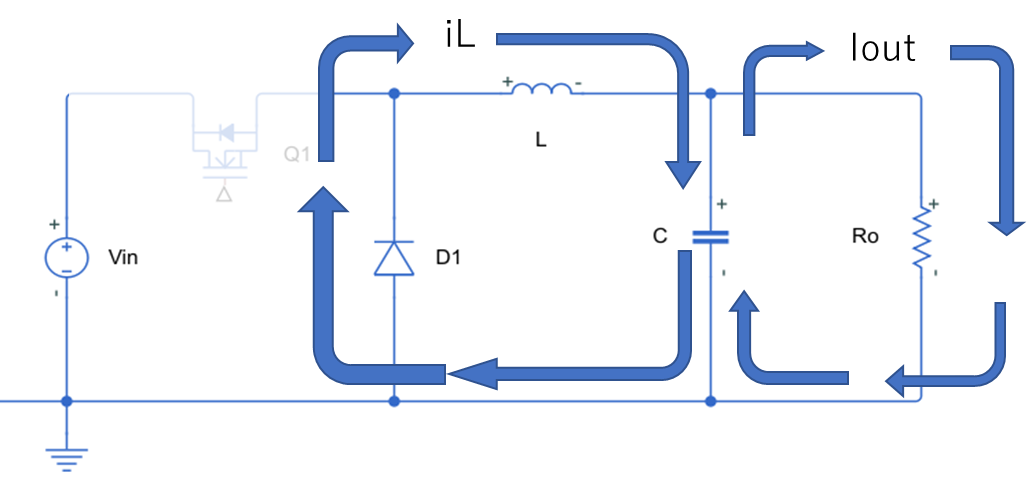

図3：スイッチOFF時におけるBuckコンバータ回路と電流経路

この回路を元に微分方程式を立てていく。

まず入力電圧$V_{\textrm{in}}$はスイッチによって切断されているため、


$$0=v_L +v_{\textrm{out}} \cdots \left(3\ldotp 1\right)$$


次にコンデンサに流入する電流$i_C$を求める。

コンデンサの両端電圧と流れる電流の関係式から(2.3)式と同様の式を得る。


$$i_C =C_1 \frac{{\textrm{dv}}_C }{\textrm{dt}}\cdots \left(3\ldotp 2\right)$$


図３から、コンデンサには流入する電流$i_L$と流出する電流$I_{\textrm{out}}$の関係は図２と変わらないため

以降立式すべき式は(2.4),(2.5),(2.6)とおなじになる。

これらの式をもとに微分方程式を立てると


$$\frac{{\textrm{di}}_L }{\textrm{dt}}=-\frac{v_C }{L_1 }\cdots \left(3\ldotp 3\right)$$



$$\frac{{d\;v}_{C\;} }{\textrm{dt}}=\frac{1}{C_1 }i_L -\frac{1}{C_1 R_o }v_C \cdots \left(3\ldotp 4\right)$$


インダクタ電流$i_L$とコンデンサ電圧$v_C$を状態変数として

一階微分方程式を導出する。


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
i_L \\
v_C 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -\frac{1}{L_1 }\\
\frac{1}{C_1 } & -\frac{1}{{C_1 R}_O }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_L \\
v_C 
\end{array}\right\rbrack \cdots \left(3\ldotp 5\right)$$


出力となる状態方程式はコンバータの出力電圧である$v_{\textrm{out}}$であるが式(2.6)よりすでに導出済みである。

式(3.5)を元に各状態空間行列を得る。


$$\mathit{\mathbf{x}}\left(t\right)=\left\lbrack \begin{array}{c}
i_L \\
v_C 
\end{array}\right\rbrack$$

$$\cdots \left(3\ldotp 6\right)$$



$$\mathit{\mathbf{u}}\left(t\right)=V_{\textrm{in}}$$

$$\cdots \left(3\ldotp 7\right)$$


Symbolic Mathで代数式を記述すると下記のようになる。

%状態空間行列を定義
Aoff=[0 -1/L1;1/C1 -1/C1/Ro]

$$Aoff = \left(\begin{array}{cc} 0 & -\frac{1}{L_{1}}\\ \frac{1}{C_{1}} & -\frac{1}{C_{1}\,\mathrm{Ro}} \end{array}\right)$$

Boff = 0

Boff = 0

Coff = [0 1]

Coff =      0     1


Doff = 0

Doff = 0

## 4．Dutyで重み付けした状態平均モデルの算出

Symbolic MathでOn時、Off時の状態空間モデルが取得できているので

ON時間およびOFF時間の時比率$\textrm{Duty}$で平均化した各状態空間行列を計算する。

これにより、平均化した状態平均化方程式、即ち状態平均モデル式(4.1)と出力方程式(4.2)を下記の通り取得することができる。


$$\begin{array}{l}
\frac{d}{\mathrm{d}t}\mathit{\mathbf{x}}\left(t\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\cdots \left(4\ldotp 1\right)\\
v_{\textrm{out}} \left(t\right)=\textrm{Cx}\left(t\right)+\textrm{Du}\left(t\right)\cdots \left(4\ldotp 2\right)
\end{array}$$


%シンボルを追加定義
syms Duty dxdt x vout u iL vc Vin

x = [iL; vc] 

$$x = \left(\begin{array}{c} \mathrm{iL}\\ \mathrm{vc} \end{array}\right)$$

u = Vin

$$u = \mathrm{Vin}$$


A = simplify(Aon*Duty + Aoff*(1-Duty))

$$A = \left(\begin{array}{cc} 0 & -\frac{1}{L_{1}}\\ \frac{1}{C_{1}} & -\frac{1}{C_{1}\,\mathrm{Ro}} \end{array}\right)$$

B = simplify(Bon*Duty + Boff*(1-Duty))

$$B = \left(\begin{array}{c} \frac{\mathrm{Duty}}{L_{1}}\\ 0 \end{array}\right)$$

C = simplify(Con*Duty + Coff*(1-Duty))

$$C = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

D = simplify(Don*Duty + Doff*(1-Duty))

$$D = 0$$

dxdt = simplify(A*x + B*u)

$$dxdt = \left(\begin{array}{c} -\frac{\mathrm{vc}-\mathrm{Duty}\,\mathrm{Vin}}{L_{1}}\\ -\frac{\mathrm{vc}-\mathrm{Ro}\,\mathrm{iL}}{C_{1}\,\mathrm{Ro}} \end{array}\right)$$

vout = C*x + D*u

$$vout = \mathrm{vc}$$

## 5.　状態平均モデルを保存する

計算結果を.matファイルとして保存する

%プロジェクトファイル情報を取得
proj = matlab.project.rootProject;
%ルートフォルダを起点に保存先を指定し、変数を保存
save( proj.RootFolder + "/Parameters/AveragedState-SapaceModel.mat",'A','B','C','D','dxdt');

## Reference

[1] 阿部　征哉, 財津　俊行, 上松 武.　デジタル電源の基礎と設計法 -スイッチング電源のデジタル制御-. 科学情報出版株式会社, 2020,246p, ISBN978-4-904774-84-7.

[2] Frede Blaabjerg, ed. Yanfelng Shen, Zian Qi and Huai Wang. Control of Power Electronic Converters And Systems. Volume 1, Chapter 3 "Modeling and Control of DC-DC Converters" p69-p92, Academic Press, 2018, ISBN 978-0-12-804254-7.

[3]MathWorks."Symbolic Math Toolbox 入門". MathWorks ヘルプセンター　ヘルプドキュメント,2022/10/19. [https://jp.mathworks.com/help/symbolic/getting-started-with-symbolic-math-toolbox.html](https://jp.mathworks.com/help/symbolic/getting-started-with-symbolic-math-toolbox.html)